# Solución numérica de ecuaciones de estado asociadas a EDOs

### Ejemplo 1

Ecuación diferencial


$$y' = \ln(t + y)\\ y(0) = 1$$


syms y(t);
Dy = diff(y,t,1);       % y'
ecu = Dy == log(t+y);   % Ecuación diferencial    
ci = y(0) == 1;         % Condiciones iniciales

 Veremos que ésta ecuación no puede ser resuelta por Matlab.

sol = dsolve(ecu,ci)    % Solucion simbólica

 
sol =
 
[ empty sym ]
 


En casos como éste, los cuales abundan en la vida real, necesitamos usar métodos numéricos para aproximar la solución de las ecuaciones.

Un método muy usado en simulaciones es el método de Runge -Kutta que puede ser ejecutado por la función **ode45** de Matlab. 

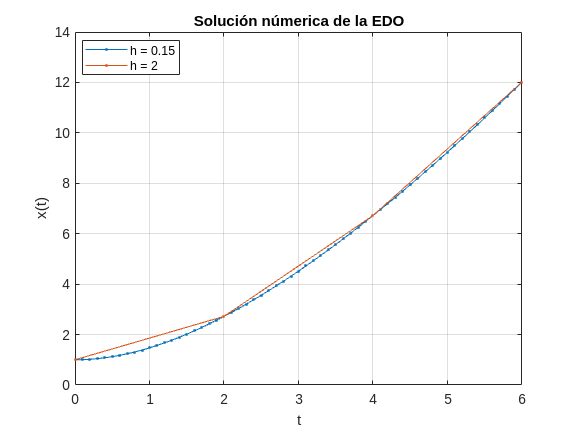

close all
syms x(t);
F = log(t + x);                     % Parte derecha de la ecuación de estado: x' = F(x,t)
F = odeFunction(F,x);               % Ecuación de estado en una forma para ser resuelta numéricamente
ci = 1;                             % Condición inicial

step = [0.1 2];                     % Algunos pasos de la solución numérica 
ti = 0;                             % Tiempo inicial           
tf = 6;                             % Tiempo final

figure
for h = step
    t = ti:h:tf;                    % Intervalo de tiempo para graficar
    [t,x1] = ode45(F,t,ci);         % Aplicación del método numérico
    plot(t,x1,'.-')
    hold on
end

title('Solución númerica de la EDO')
grid on
xlabel('t')
ylabel('x(t)')  
legend({'h = 0.15','h = 2'}, 'location', 'best')

### Ejemplo 2

Ecuación diferencial: 


$$y'' + 4y' + 2y = ln(t+1)\\
y(0) = 1\\
 y'(0) = -1.$$


En este ejemplo, comparamos la solución analítica obtenida con Matlab con la solución numérica obtenida al usar **ode45**.

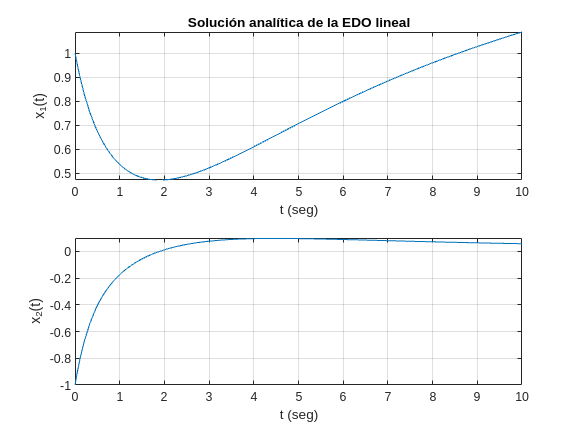

close all
syms x1(t) x2(t);

Dx1 = diff(x1,t,1);                 % Primeras derivadas de cada variable de estado 
Dx2 = diff(x2,t,1); 

g = log(t+1);                       % Entrada o término independiente

ecu1 = Dx1 == x2 ;                  % Ecuación de estado asociada 1
ecu2 = Dx2 == -2*x1 - 4*x2 + g;     % Ecuación de estado asociada 2

ci1 = x1(0) == 1;                   % Condicion inicial x1
ci2 = x2(0) == -1;                  % Condicion inicial x2

x = dsolve([ecu1 ecu2],[ci1 ci2]);  % Resuelva la ecuación de estado
x_1 = x.x1; x_2 = x.x2;             

t = [0 10];                         % Intervalo del tiempo

% Gráficas de las soluciones
figure
subplot(2,1,1)
fplot(x_1,t)
title('Solución analítica de la EDO lineal') 
grid on
xlabel('t (seg)') 
ylabel('x_1(t)')

subplot(2,1,2)
fplot(x_2,t)
grid on
xlabel('t (seg)') 
ylabel('x_2(t)')

Ahora aproximaremos la solución por el método de Runge-Kutta y comparamos el resultado con la solución analítica.

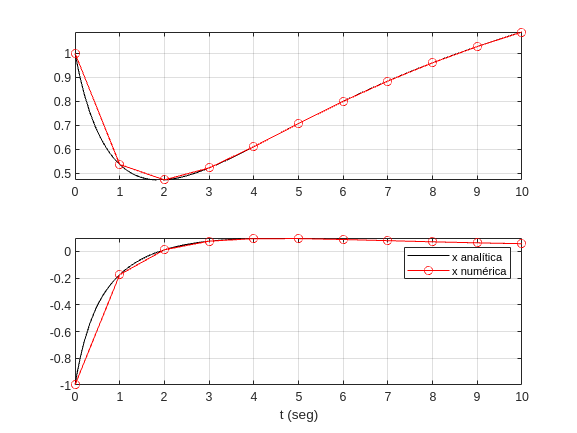

close all
F1 = x2;                                % Parte derecha de la ecuación de estado: x' = F(x,t)
F2 = -2*x1 -4*x2 + g; 

F = odeFunction([F1 F2],[x1 x2]);       % Ecuación de estado 

ci = [1; -1];                           % Condiciones iniciales 

h = 1;                                  % Paso de la solución numérica
t_ode = 0:h:10;                             % Intervalo de tiempo para graficar 

[t_ode,ode_sol] = ode45(F,t_ode,ci); % Aplicación del método numérico de Runge-Kutta de un solo paso: x(k) se calcula a partir de x(k-1)

% Gráficas de las soluciones
figure
subplot(2,1,1)
title('Solución analítica vs numérica')
fplot(x_1,t,'k')
hold on
plot(t_ode,ode_sol(:,1),'ro-')
grid on

subplot(2,1,2)
fplot(x_2,t,'k')
hold on
plot(t2,ode_sol(:,2),'ro-')
grid on

xlabel('t (seg)'), 
legend({'x analítica', 'x numérica'})

### Ejemplo 3

Ecuación diferencial:

 
$$x' = (t + x)/(t - x)\\
x(1) = 0. $$


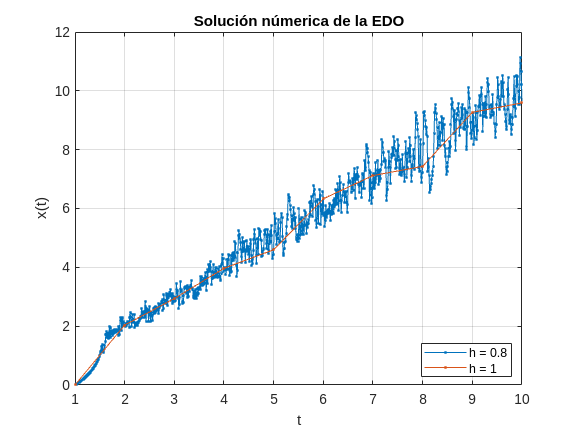

close all
syms x(t)

F = (t+x)/(t-x);                    % Parte derecha de la ecuación de estado: x' = F(x,t)
F = odeFunction(F,x);               % Ecuación de estado 

ci = 0;                             % Condición inicial 

step = [0.01 1];                     % Algunos pasos de la solución numérica 
ti = 1;                             % Tiempo inicial           
tf = 10;                             % Tiempo final

% Gráficas de las soluciones
figure
for h = step
    t = ti:h:tf;                    % Intervalo de tiempo para graficar
    [t,x1] = ode45(F,t,ci);         % Aplicación del método numérico
    plot(t,x1,'.-')
    hold on
end

title('Solución númerica de la EDO')
grid on
xlabel('t')
ylabel('x(t)')  
legend({'h = 0.8','h = 1'}, 'location', 'best')

### Ejemplo 4

Ecuación diferencial no lineal: $\ddot{y} +4y\dot{y} +{2y}^2 =\ln \left(t+1\right)$

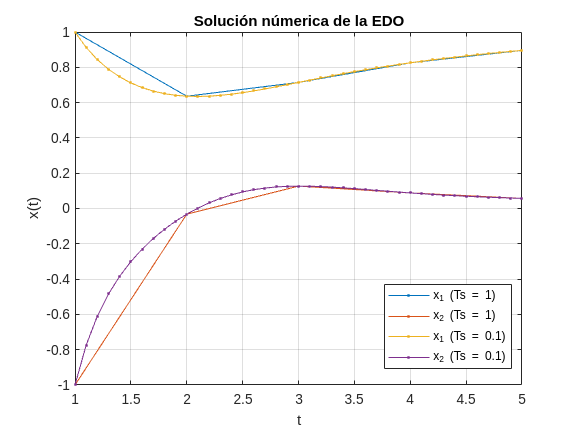

close all
syms x1(t) x2(t)
u = log(t+1);                           % Entrada o término independiente
f1 = x2;                                % Parte derecha de la ecuación de estado: x' = f(x)
f2 = -2*x1^2 -4*x1*x2 + u;     
F = odeFunction([f1 f2],[x1 x2]);       % Ecuación de estado en una forma para ser resuelta numéricamente

ci = [1; -1];                           % Condiciones iniciales numéricas
step = [1 0.1];                         % Paso de la solución numérica

ti = 1;                                 % Tiempo inicial           
tf = 5;                                 % Tiempo final

% Gráficas de las soluciones
figure
for h = step
    t = ti:h:tf;                        % Intervalo de tiempo para graficar
    [t,x1] = ode45(F,t,ci);             % Aplicación del método numérico
    plot(t,x1,'.-')
    hold on
end

title('Solución númerica de la EDO')
grid on
xlabel('t')
ylabel('x(t)')  

legend({'x_1 (Ts = 1)','x_2 (Ts = 1)','x_1 (Ts = 0.1)','x_2 (Ts = 0.1)'},"Location","best")